# Reading and Displaying Images in MATLAB

%The function imfinfo retrieves essential metadata from most image formats
%Some formats will include additional metadata in the file itself
%Special image reading libraries can be used to retrieve that

%Along with this live script, the zip file includes 3 images:
%grayscale.jpg
%color.jpg
%grayscale.tif
%multidimensional.tif

%Read image and check basic image properties
info = imfinfo('multidimensional.tif');
%Note how this time info is actually an array with 35 entries, this is
%becuse the multidimensional.tif file contains a 3D image with 35 planes
length(info)

ans = 35

%We can pull the relevant parameters from the 1st page of the image file
info(1).Width

ans = 388

info(1).Height

ans = 269

info(1).BitDepth

ans = 16

info(1).ColorType

ans = 'grayscale'

%In order to read a 3D file, we first have to build an empty matrix of the
%same size in order to store it. For this, we can use the 'zeros' command
%which will create a matrix full of zeros of any size

%Remember that MATLAB dimensions are always in the order of rows, columns,
%pages, so we use the Height of the image as the number of rows, the Width
%as the number of columns, and the 'length' of the info vector tells us how
%many pages there are in the multidimensional.tif file. Finally we tell the
%zeros command to make this matrix out of uint16 numbers, since that's the
%data type of the original image

img = zeros(info(1).Height,info(1).Width,length(info),'uint16');

%Refer back to Module 5 of the MATLAB onramp for indexing arrays for a
%refresher

%Once we have the placeholder variable made, we can use variable indexing
%to load each page into it one at a time. For example:
img(:,:,1) = imread('multidimensional.tif',1);

%But this is a pain to do by hand for all 35, so let's automate it using a
%FOR Loop. For a guide on FOR loops, refer to the documentation:
%https://www.mathworks.com/help/matlab/ref/for.html
for i = 1:length(info)
    img(:,:,i) = imread('multidimensional.tif',i);
end

%To understand what's going on here, let's break it down. A FOR loop will
%run the code between the for and end statements for a fixed number of
%iterations. The number of iterations is controlled by the length of the
%"index" variable that's defined by the for statement. In this case, we're
%naming the "index" variable as "i" and setting it equal to the range of 1
%until the length of the info variable, which is 35. So we're defining the
%variable i as a vector [1, 2, 3, ... 35]. Each iteration of the loop, the
%value of "i" will be set to the position of the vector that corresponds to
%the current iteration of the loop. So on the first iteration, i will be
%equal to 1, so the first page of the variable "img" (defined by indexing
%img(:,:,i)) will be set to the image read from the first page of the tif
%file by imread('multidimensional.tif',1). The 2nd iteration, i will be 2,
%and so on until the 35th iteration, after which the for loop will end.

size(img)

ans =    269   388    35


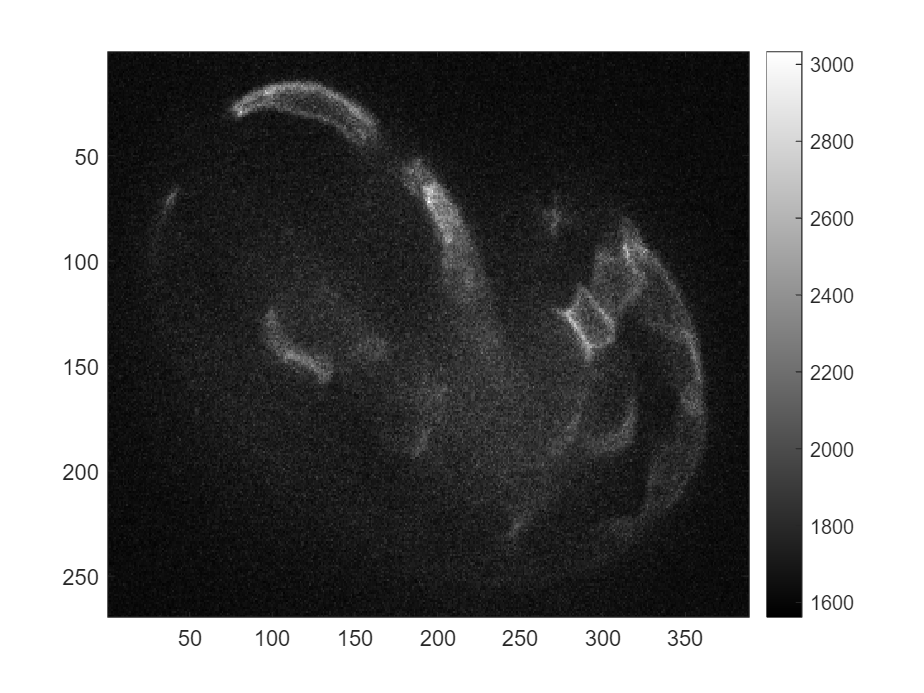

%Since this is a 3D image, we can display it in one of a few different
%ways

%Since the bitdepth of the image is 16, we'll use imagesc first to display
%specific pages of the image, for example this will display only the 15th
%page of the image
imagesc(img(:,:,15))
%The command colormap allows the values of the image to be mapped to
%arbitrary colors to make it easier to see differences, but we'll stick to
%grayscale for now
colormap gray
%The command colorbar displays a key to how different gray values are
%mapped to specific image values
colorbar

%What if we want to have an interactive view that allows us to easily move
%through each individual page in the image? For this we can use the
%sliceviewer
sliceViewer(img)

'sliceViewer' requires one of the following:
  Image Processing Toolbox
  Medical Imaging Toolbox

%The range of values over which the intensity is scaled can be adjusted
%using the "DisplayRange" parameter like this:
sliceViewer(img,"DisplayRange",[1700,3500])

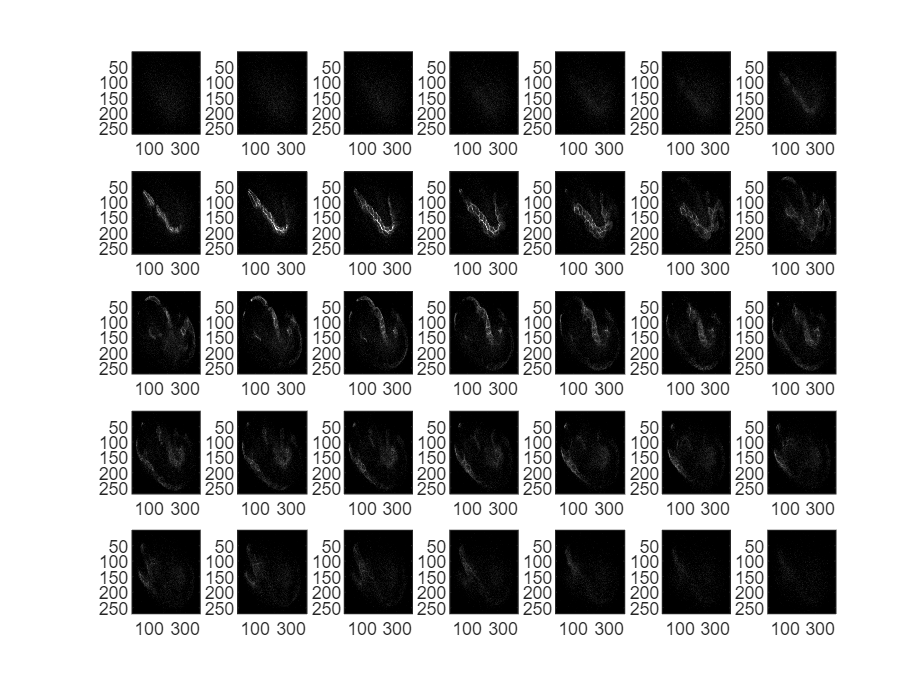

%Viewing one slice at a time makes it easy to see small structures that may
%be buried in a large image, but makes it hard to see the whole image all
%at once, we can play around with displaying every slice in sequence using
%subplot. In this case we have 35 images, so let's try making a 5x7 grid in
%which to display every image
for i = 1:length(info)
    subplot(5,7,i);
    imagesc(img(:,:,i),[1700,3500])
end

img = imread('color.jpg')

img = 1063×1600×3 uint8 array
img(:,:,1) =

    26    26    26    26    26    26    26    26    28    28    27    27    27    27    27    28    31    32    32    32    31    31    29    29    22    23    23    24    24    25    26    26    21    19    19    19    19    18    17    17    11    15    18    18    16    16    19    22    21    20    19    18    16    15    14    13    16    16    16    17    17    18    18    18    17    17    18    18    19    19    22    22    21    22    21    22    23    24    23    23    18    21    21    18    19    22    24    21    20    22    24    23    21    20    22    21    15    12    12    12    13    13    12    12    15    10     7     6     8     9     6     2     3     3     3     3     3     4     4     4     4     4     4     3     3     3     3     3     6     7     9     9     8     9    11    12    11    11    13    14    15    15    16    16    13    13    13    13    14    14    12    12    11    11     9     7     6     5     4  

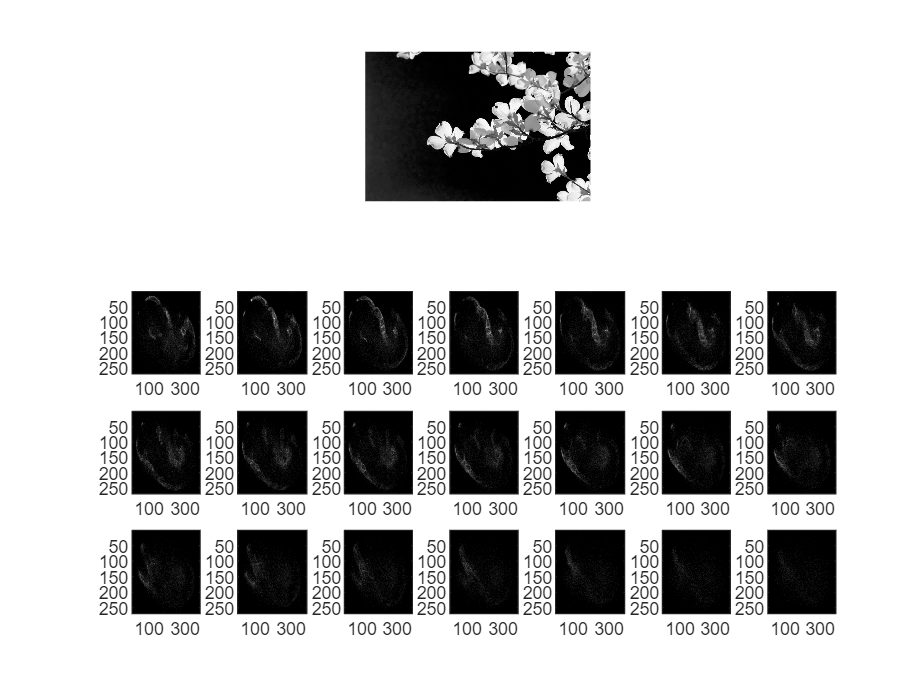

subplot(3,1,1)
imshow(img(:,:,1)) 


% pull out average of each color 
red = mean(img(:,:,1), 'all') 
green = mean(img(:,:,2),'all')
blue = mean(img(:,:,3), 'all')

% pixel value distribution and apply segmentation 
hist(double(red(:)), 50) %intervals of 50
xlabel('Pixel Intensities'); 

%apply range to image such as 
%changing imagesc(img) 
% non-linear intensity mapping: Gamma 
imagesc(img, [1700,4500]); 

info = imfinfo('multidimensional.tif') %reading multidimensional images 
img = zeros(269, 388, 35, 'uint16'); % initialize an empty vriable to store data 
% 269 rows, 388 cols, 35 pages, 16 bit 
% fill in with for loop
for i = 1:35
    img(:,:,i) = imread('multidimensional.tif', i);
end 


sliceviewer(img) 
volumeviewer(img) 

% displaying multidimensional images 
imshow(max(img,[], 3)); % this is called a max projection 

for i = 1:35
    img(:,:, i) = imwrite('multidimensional.tif', i)
end 

